# 4.1 - Least Squares

## 8b

x=[1;3;4;6]

x =      1
     3
     4
     6


y=[2;2;1;3]

y =      2
     2
     1
     3


A=[1,1;1,3;1,4;1,6]

A =      1     1
     1     3
     1     4
     1     6


b=[2;2;1;3]

b =      2
     2
     1
     3


c=(A'*A)\(A'*b)

c =     1.4615
    0.1538


f=@(x) c(1) + c(2)*x;
scatter(x, y)
hold on;
plot(0:0.1:10,(f(0:0.1:10)))

## 9b

A=[x.^0 x.^1 x.^2]

A =      1     1     1
     1     3     9
     1     4    16
     1     6    36


c=(A'*A)\(A'*b)

c =     2.9615
   -1.0128
    0.1667


r=b-A*c

r =    -0.1154
    0.5769
   -0.5769
    0.1154


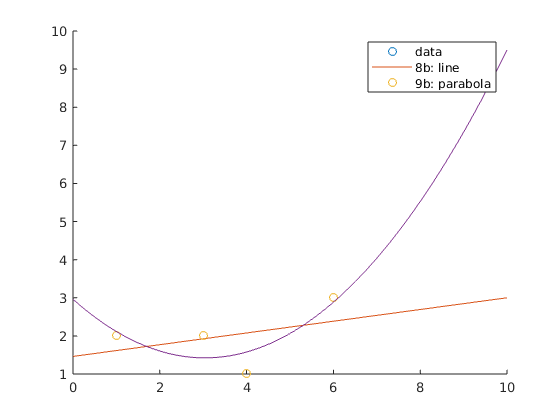

f=@(x) c(1) + c(2)*x + c(3)*x.^2;
scatter(x, y)
plot(0:0.1:10,(f(0:0.1:10)))
legend('data', '8b: line', '9b: parabola')
hold off;

## CP3

Data set:

years = [1960 1970 1990 2000]'

years =         1960
        1970
        1990
        2000


populations = [3039585530 3707475887 5281653820 6079603571]'

populations = 	1.0e+09 *

    3.0396
    3.7075
    5.2817
    6.0796


x = (years - 1960) / 10

x =      0
     1
     3
     4


Using the method of least squares:

[c_line, rmse_line] = least_squares(x, populations, 2)

c_line = 	1.0e+09 *

    2.9962
    0.7654


rmse_line = 3.6751e+07

[c_parabola, rmse_parabola] = least_squares(x, populations, 3)

c_parabola = 	1.0e+09 *

    3.0288
    0.6787
    0.0217


rmse_parabola = 1.7130e+07

line = @(x) c_line(1) + c_line(2)*x

line = function_handle with value:
    @(x)c_line(1)+c_line(2)*x


parabola = @(x) c_parabola(1) + c_parabola(2)*x + c_parabola(3)*x.^3

parabola = function_handle with value:
    @(x)c_parabola(1)+c_parabola(2)*x+c_parabola(3)*x.^3


Plotting:

scatter(x, populations)
hold on;
axis = 0:0.1:10

axis =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


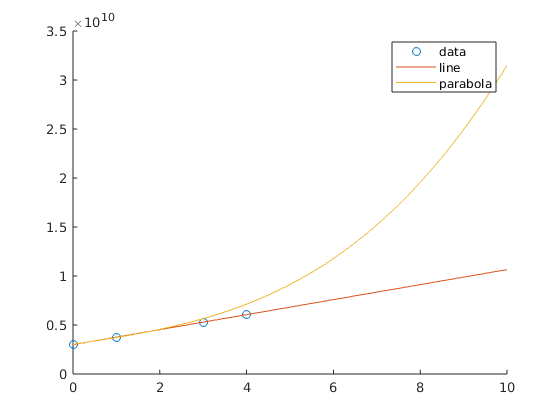

plot(axis, line(axis))
plot(axis, parabola(axis))
legend('data', 'line', 'parabola')
hold off;

Finding the root mean squared error:

sprintf('RMSE of line: %e', rmse_line)

ans = 'RMSE of line: 3.675109e+07'

sprintf('RMSE of parabola: %e', rmse_parabola)

ans = 'RMSE of parabola: 1.712971e+07'

The parabola seems like an improvement (but the graph shows the points in a fairly straight line)

function [c, RMSE] = least_squares(x, y, n)
[m, ~] = size(x);
% dynamic A for any n
A = x.^(0:n-1);
% the usual A'Ac=A'b
c = (A'*A)\(A'*y);
% calculate RMSE too
RMSE = sqrt(sum((y - A*c).^2) / m);
end

% could be used for plotting
function y = plottable(x, c, n)
[m, ~] = size(x);
y = zeros(m, 1);
for j=1:n
    y = y + c(j).*x.^(j-1);
end
end